# Robot Kinematics and Dynamics

## Getting a robot

Let's start by importing a robot.

load exampleRobots.mat
robot = importrobot('iiwa14.urdf')

robot =   RigidBodyTree with properties:

     NumBodies: 10
        Bodies: {1×10 cell}
          Base: [1×1 robotics.RigidBody]
     BodyNames: {'iiwa_link_0'  'iiwa_link_1'  'iiwa_link_2'  'iiwa_link_3'  'iiwa_link_4'  'iiwa_link_5'  'iiwa_link_6'  'iiwa_link_7'  'iiwa_link_ee'  'iiwa_link_ee_kuka'}
      BaseName: 'world'
       Gravity: [0 0 0]
    DataFormat: 'struct'


showdetails(robot)

--------------------
Robot: (10 bodies)

 Idx                Body Name                Joint Name                Joint Type                Parent Name(Idx)   Children Name(s)
 ---                ---------                ----------                ----------                ----------------   ----------------
   1              iiwa_link_0          world_iiwa_joint                     fixed                        world(0)   iiwa_link_1(2)  
   2              iiwa_link_1              iiwa_joint_1                  revolute                  iiwa_link_0(1)   iiwa_link_2(3)  
   3              iiwa_link_2              iiwa_joint_2                  revolute                  iiwa_link_1(2)   iiwa_link_3(4)  
   4              iiwa_link_3              iiwa_joint_3                  revolute                  iiwa_link_2(3)   iiwa_link_4(5)  
   5              iiwa_link_4              iiwa_joint_4                  revolute                  iiwa_link_3(4)   iiwa_link_5(6)  
   6              iiwa_link_

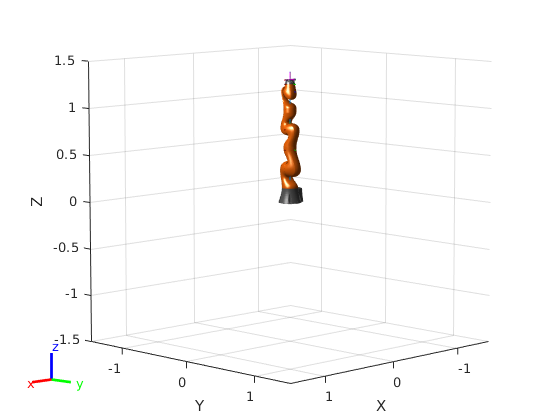

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


% ee_name = iiwa_link_ee_kuka
ee_name = robot.BodyNames(end);
ee_name = ee_name{1};
show(robot)

We can then perform kinematic operations such as:

#### Transforms

config = randomConfiguration(robot);
% Compute transform w.r.t world frame (BaseName property of the robot)
wT3 = getTransform(robot, config, 'iiwa_link_3');
% Compute transform w.r.t other frame
bT3 = getTransform(robot, config, 'iiwa_link_3', 'iiwa_link_0');

We can also do transforms symbolically/manually

syms Rx(q) Rz(q) Ry(q) Tx(l) Ty(l) Tz(l) q1 q2 q3 l1 l2;
Rx(q) = [1  0       0       0; 
         0  cos(q)  -sin(q) 0; 
         0  sin(q)  cos(q)  0; 
         0  0       0       1];
Ry(q) = [cos(q)  0   sin(q) 0; 
         0       1   0      0; 
         -sin(q) 0   cos(q) 0; 
         0       0   0      1];
Rz(q) = [cos(q) -sin(q) 0   0;     
         sin(q) cos(q)  0   0; 
         0      0       1   0; 
         0      0       0   1];
Tx(l) = [1 0 0 l; 
         0 1 0 0; 
         0 0 1 0; 
         0 0 0 1];
Ty(l) = [1 0 0 0; 
         0 1 0 l; 
         0 0 1 0; 
         0 0 0 1];
Tz(l) = [1 0 0 0; 
         0 1 0 0; 
         0 0 1 l; 
         0 0 0 1];
% Forward Kinematic map (x(q)) for two link planar robot
X = Rz(q1) * Tx(l1) * Rz(q2) * Tx(l2);

#### Jacobians

Numerical analysis

config = randomConfiguration(robot);
J = geometricJacobian(robot, config, ee_name)

J =     0.0000    0.9952   -0.0753   -0.7245    0.5285   -0.6662    0.2431
   -0.0000    0.0978    0.7656   -0.4822    0.0701    0.6519    0.6490
    1.0000    0.0000    0.6388    0.4926    0.8460    0.3622   -0.7209
   -0.4314    0.0505    0.1194   -0.1735   -0.0756   -0.0888    0.0000
    0.2104   -0.5134    0.1733    0.2986    0.0739   -0.0494   -0.0000
   -0.0000    0.4087   -0.1936    0.0372    0.0411   -0.0745    0.0000


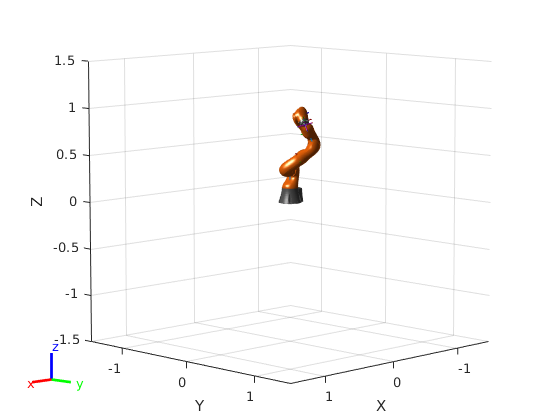

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


show(robot, config)

#### Inverse Kinematics

First we need to make an IK solver

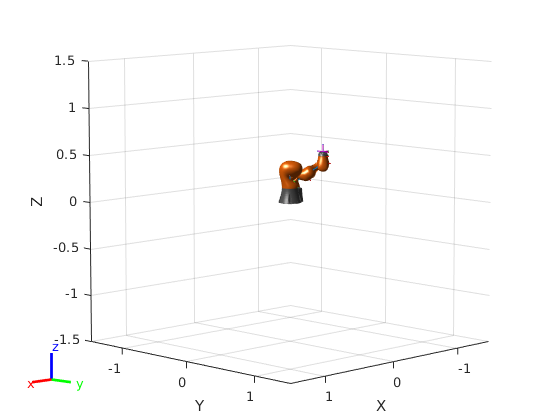

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ik = robotics.InverseKinematics('RigidBodyTree', robot);
goalPose = double(Rz(pi/2) * Tz(0.5) * Ty(0.5)); % Need to convert to numeric
% OR random configuration
% randConfig = robot.randomConfiguration;
% pose = getTransform(robot,randConfig,'ee_name','world');

% Weight for pose tolerances (Elements 1-3 for rotation, 4-6 for translation)
weights = [0.25 0.25 0.25 1 1 1];
initialGuess = robot.homeConfiguration;
[configSoln, solnInfo] = ik(ee_name, goalPose, weights, initialGuess);
show(robot, configSoln)

#### Inverse Dynamics

We can perform inverse dynamic calculations to counter external forces. In this case gravity, and 2 other forces on a link and EE.

lbr.DataFormat = 'row';
lbr.Gravity = [0 0 -9.81];  
q = homeConfiguration(lbr);
F_1 = externalForce(lbr, 'link_1', [0 0 0.0 0.1 0 0]);
F_2 = externalForce(lbr, 'tool0', [0 0 0.0 0.1 0 0], q);
% Compute the Inv. Dyn. for a robot (1) in a given joint configuration (2) assuming
% joint velocities (3) and accelerations (4) are 0, where certain forces
% (5) are being applied.
tau = inverseDynamics(lbr,q,[],[],fext1+fext2);

## Constraints

Sometimes we want the robot to respect some constraints imposed on its workspace or configuration, such as avoiding collisions or moving in a certain orientation.

We can use RST's constraint tools to apply them on the robot. For example, we can limit the workspace of the end effector using C`artesianBounds`

% xMin xMax; yMin yMax; zMin zMax
bounds = [-1 1; -1 1; -1 1;];

bounds =     -1     1
    -1     1
    -1     1


cartConst = robotics.CartesianBounds(ee_name, 'Bounds', bounds);

Or we can limit the joint positions allowed on the robot using an $n\times2$ matrix (min, max)

bounds = [-pi/2 pi/2; -pi/2 pi/2; -pi/2 pi/2; -pi/2 pi/2; -pi/2 pi/2; -pi/2 pi/2; -pi/2 pi/2;];

bounds =    -1.5708    1.5708
   -1.5708    1.5708
   -1.5708    1.5708
   -1.5708    1.5708
   -1.5708    1.5708
   -1.5708    1.5708
   -1.5708    1.5708


jointConst = robotics.JointPositionBounds(robot, 'Bounds', bounds);

jointConst =   JointPositionBounds with properties:

     Bounds: [7×2 double]
    Weights: [1 1 1 1 1 1 1]
